## Q2 - part d | ARX

clc; clear

%%

load HW5_question2

u3 = Z3.u;
y3 = Z3.y;

u3_val = u3;%(601:end);
y3_val = y3;%(601:end);

u3 = u3(1:600);
y3 = y3(1:600);


%%

% System Z3 **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> System III Identification Begins:------------------------------\n")

>>> System III Identification Begins:------------------------------


%%

Ts = 0.5; 
t = 0:Ts:length(u3)*Ts-Ts;
t_val = 0:Ts:length(u3_val)*Ts-Ts;
N = length(y3);
N_val = length(y3_val);

%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    U = arx_U_builder_3(u3, y3, na, nb, nk);
    theta_hat_3 = inv(U'*U)*U'*y3;
    y_hat_3 = form_tf_lsim_2(theta_hat_3, u3, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y3, y_hat_3);

    error = y3 - y_hat_3;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.037676 | MSE=134.281067 | var=134.730167 | s_hat=80568.640040 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.540160 | MSE=64.165287 | var=64.595926 | s_hat=38499.171934 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.476586 | MSE=73.036351 | var=73.774092 | s_hat=43821.810427 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.713941 | MSE=39.916142 | var=40.455549 | s_hat=23949.685132 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.893466 | MSE=14.865532 | var=15.117490 | s_hat=8919.319271 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.967564 | MSE=4.526087 | var=4.618456 | s_hat=2715.652231 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.991868 | MSE=1.134722 | var=1.161831 | s_hat=680.832959 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.996783 | MSE=0.448886 | var=0.461185 | s_hat=269.331754 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.997651 | MSE=0.327802 | var=0.337940 | s_hat=196.681234 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.997778 | MSE=0.310065 | var=0.320757 | s_hat=186.038869 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.997790 | MSE=0.308351 | var=0.320088 | s_hat=185.010861 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.997740 | MSE=0.315409 | var=0.328551 | s_hat=189.245295 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.997671 | MSE=0.324989 | var=0.339709 | s_hat=194.993197 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.997397 | MSE=0.363212 | var=0.380992 | s_hat=217.927334 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.997035 | MSE=0.413730 | var=0.435505 | s_hat=248.237757 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.997138 | MSE=0.399362 | var=0.421862 | s_hat=239.617339 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.997159 | MSE=0.396445 | var=0.420260 | s_hat=237.866893 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.997293 | MSE=0.377778 | var=0.401892 | s_hat=226.666897 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.997476 | MSE=0.352199 | var=0.376013 | s_hat=211.319345 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.997515 | MSE=0.346708 | var=0.371473 | s_hat=208.025016 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.997582 | MSE=0.337452 | var=0.362852 | s_hat=202.471239 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.997631 | MSE=0.330511 | var=0.356666 | s_hat=198.306328 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.997581 | MSE=0.337533 | var=0.365560 | s_hat=202.519980 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.997551 | MSE=0.341713 | var=0.371427 | s_hat=205.027945 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.997706 | MSE=0.320058 | var=0.349154 | s_hat=192.034698 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.997743 | MSE=0.314997 | var=0.344888 | s_hat=188.998399 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.997724 | MSE=0.317628 | var=0.349042 | s_hat=190.576809 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.997750 | MSE=0.313997 | var=0.346320 | s_hat=188.397969 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.997759 | MSE=0.312685 | var=0.346146 | s_hat=187.611233 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.997790 | MSE=0.308343 | var=0.342603 | s_hat=185.005600 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.997775 | MSE=0.310408 | var=0.346180 | s_hat=186.244879 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.997765 | MSE=0.311821 | var=0.349053 | s_hat=187.092591 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.997734 | MSE=0.316128 | var=0.355200 | s_hat=189.676936 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.997684 | MSE=0.323122 | var=0.364424 | s_hat=193.873499 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.997640 | MSE=0.329295 | var=0.372786 | s_hat=197.576820 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.997680 | MSE=0.323744 | var=0.367891 | s_hat=194.246219 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.997699 | MSE=0.321147 | var=0.366327 | s_hat=192.688172 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.997712 | MSE=0.319331 | var=0.365646 | s_hat=191.598683 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.997691 | MSE=0.322224 | var=0.370373 | s_hat=193.334604 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.997642 | MSE=0.329000 | var=0.379615 | s_hat=197.399757 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.997697 | MSE=0.321321 | var=0.372187 | s_hat=192.792744 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.997682 | MSE=0.323459 | var=0.376115 | s_hat=194.075191 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.997683 | MSE=0.323274 | var=0.377363 | s_hat=193.964556 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.997710 | MSE=0.319541 | var=0.374462 | s_hat=191.724425 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.997704 | MSE=0.320318 | var=0.376844 | s_hat=192.190693 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.997714 | MSE=0.318950 | var=0.376712 | s_hat=191.369856 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.997734 | MSE=0.316174 | var=0.374910 | s_hat=189.704334 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.997711 | MSE=0.319439 | var=0.380285 | s_hat=191.663534 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.997706 | MSE=0.320118 | var=0.382612 | s_hat=192.071052 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.997690 | MSE=0.322340 | var=0.386809 | s_hat=193.404252 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.997782 | MSE=0.309542 | var=0.372942 | s_hat=185.725116 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.997716 | MSE=0.318775 | var=0.385614 | s_hat=191.264761 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.997823 | MSE=0.303798 | var=0.368985 | s_hat=182.278733 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.997822 | MSE=0.303920 | var=0.370634 | s_hat=182.352156 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.997835 | MSE=0.302087 | var=0.369902 | s_hat=181.251995 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.997793 | MSE=0.307900 | var=0.378565 | s_hat=184.739957 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.997736 | MSE=0.315880 | var=0.389976 | s_hat=189.528268 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.997734 | MSE=0.316140 | var=0.391909 | s_hat=189.683809 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.997766 | MSE=0.311723 | var=0.388037 | s_hat=187.033784 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.997779 | MSE=0.309949 | var=0.387436 | s_hat=185.969292 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.997895 | MSE=0.293780 | var=0.368762 | s_hat=176.268239 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.997836 | MSE=0.301975 | var=0.380641 | s_hat=181.184997 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.997874 | MSE=0.296670 | var=0.375531 | s_hat=178.001929 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.997862 | MSE=0.298335 | var=0.379239 | s_hat=179.000954 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.997872 | MSE=0.296878 | var=0.378993 | s_hat=178.126711 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.997895 | MSE=0.293782 | var=0.376644 | s_hat=176.269385 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.997967 | MSE=0.283622 | var=0.365179 | s_hat=170.173254 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.997979 | MSE=0.281996 | var=0.364650 | s_hat=169.197672 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.997944 | MSE=0.286912 | var=0.372613 | s_hat=172.147173 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.997965 | MSE=0.283981 | var=0.370410 | s_hat=170.388495 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.997965 | MSE=0.284017 | var=0.372075 | s_hat=170.410209 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.997983 | MSE=0.281512 | var=0.370410 | s_hat=168.907174 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.997977 | MSE=0.282352 | var=0.373153 | s_hat=169.411395 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.998027 | MSE=0.275371 | var=0.365537 | s_hat=165.222601 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.998043 | MSE=0.273123 | var=0.364164 | s_hat=163.873715 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.998036 | MSE=0.274002 | var=0.366967 | s_hat=164.401187 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.998062 | MSE=0.270373 | var=0.363730 | s_hat=162.223776 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.998051 | MSE=0.272011 | var=0.367583 | s_hat=163.206739 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.998068 | MSE=0.269633 | var=0.366017 | s_hat=161.779721 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.998092 | MSE=0.266291 | var=0.363123 | s_hat=159.774333 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.998098 | MSE=0.265418 | var=0.363586 | s_hat=159.250706 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.998091 | MSE=0.266392 | var=0.366595 | s_hat=159.835215 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.998097 | MSE=0.265598 | var=0.367186 | s_hat=159.358933 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.998115 | MSE=0.263005 | var=0.365285 | s_hat=157.803160 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.998125 | MSE=0.261684 | var=0.365140 | s_hat=157.010275 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.998156 | MSE=0.257270 | var=0.360658 | s_hat=154.361823 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.998153 | MSE=0.257711 | var=0.362973 | s_hat=154.626413 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.998139 | MSE=0.259715 | var=0.367521 | s_hat=155.828814 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.998183 | MSE=0.253520 | var=0.360455 | s_hat=152.111982 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.998189 | MSE=0.252748 | var=0.361069 | s_hat=151.648920 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.998196 | MSE=0.251781 | var=0.361408 | s_hat=151.068345 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.998187 | MSE=0.252955 | var=0.364838 | s_hat=151.772804 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.998193 | MSE=0.252101 | var=0.365364 | s_hat=151.260641 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.998177 | MSE=0.254381 | var=0.370458 | s_hat=152.628537 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.998138 | MSE=0.259881 | var=0.380314 | s_hat=155.928879 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.998133 | MSE=0.260451 | var=0.383017 | s_hat=156.270861 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.998145 | MSE=0.258903 | var=0.382616 | s_hat=155.342083 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.998164 | MSE=0.256245 | var=0.380563 | s_hat=153.747277 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.998151 | MSE=0.257965 | var=0.385022 | s_hat=154.778924 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.998206 | MSE=0.250343 | var=0.375514 | s_hat=150.205615 | 


-------------------------------------------------------------



fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

BestFitU = arx_U_builder_3(u3, y3, na, nb, nk);
BestFitModel_3 = inv(BestFitU'*BestFitU)*BestFitU'*y3;
BestFit_y_hat_3 = form_tf_lsim_2(BestFitModel_3, u3_val, t_val, na, Ts);

G =
 
                                                                                                         
     0.6068 z^-1 + 1.827 z^-2 + 2.583 z^-3 + 2.919 z^-4 + 2.768 z^-5 + 2.247 z^-6 + 1.449 z^-7           
                                                                                                         
             + 0.6307 z^-8 - 0.02605 z^-9 - 0.4093 z^-10 - 0.4203 z^-11 - 0.05112 z^-12 + 0.5525 z^-13   
                                                                                                         
             + 1.381 z^-14 + 2.126 z^-15 + 2.472 z^-16 + 2.478 z^-17 + 2.146 z^-18 + 1.479 z^-19         
                                                                                                         
             + 0.7155 z^-20 + 0.1303 z^-21 - 0.147 z^-22 - 0.06341 z^-23 + 0.2501 z^-24 + 0.7939 z^-25   
                                                                                                         
             + 1.412 z^-26 + 1.904 z^-27

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 11 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 11 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarU = arx_U_builder_3(u3, y3, na, nb, nk);
VarModel_3 = inv(VarU'*VarU)*VarU'*y3;
Var_y_hat_3 = form_tf_lsim_2(VarModel_3, u3_val, t_val, na, Ts);

G =
 
                                                                                                      
   0.6147 z^-1 + 1.681 z^-2 + 2.089 z^-3 + 1.993 z^-4 + 1.377 z^-5 + 0.597 z^-6 - 0.1374 z^-7         
                                                                                                      
                                             - 0.5972 z^-8 - 0.6874 z^-9 - 0.4626 z^-10 - 0.1979 z^-11
                                                                                                      
  ------------------------------------------------------------------------------------------------------
                                                                                                        
  1 - 0.2284 z^-1 - 0.1256 z^-2 + 0.1043 z^-3 + 0.0761 z^-4 + 0.05185 z^-5 + 0.1282 z^-6 + 0.05207 z^-7 
                                                                                                        
                                          - 0.04543 z^-8 - 


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 10 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 10 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

AICU_3 = arx_U_builder_3(u3, y3, na, nb, nk);
AICModel_3 = inv(AICU_3'*AICU_3)*AICU_3'*y3;
AIC_y_hat_3 = form_tf_lsim_2(AICModel_3, u3_val, t_val, na, Ts);

G =
 
                                                                                                      
   0.6038 z^-1 + 1.614 z^-2 + 1.888 z^-3 + 1.601 z^-4 + 0.8604 z^-5 + 0.1175 z^-6 - 0.4492 z^-7       
                                                                                                      
                                                            - 0.6673 z^-8 - 0.5011 z^-9 - 0.1655 z^-10
                                                                                                      
  -----------------------------------------------------------------------------------------------------
                                                                                                       
  1 - 0.3235 z^-1 - 0.193 z^-2 + 0.0683 z^-3 + 0.0702 z^-4 + 0.06747 z^-5 + 0.1316 z^-6 + 0.06712 z^-7 
                                                                                                       
                                                          - 0.0


fprintf("=================================================================\n")

%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.21 as


fprintf("    Degree = %d \n", winner)

    Degree = 10 



na = winner;
nb = winner;
p = na+nb;

FTestU_3 = arx_U_builder_3(u3, y3, na, nb, nk);
FTestModel_3 = inv(FTestU_3'*FTestU_3)*FTestU_3'*y3;
FTest_y_hat_3 = form_tf_lsim_2(FTestModel_3, u3_val, t_val, na, Ts);

G =
 
                                                                                                      
   0.6038 z^-1 + 1.614 z^-2 + 1.888 z^-3 + 1.601 z^-4 + 0.8604 z^-5 + 0.1175 z^-6 - 0.4492 z^-7       
                                                                                                      
                                                            - 0.6673 z^-8 - 0.5011 z^-9 - 0.1655 z^-10
                                                                                                      
  -----------------------------------------------------------------------------------------------------
                                                                                                       
  1 - 0.3235 z^-1 - 0.193 z^-2 + 0.0683 z^-3 + 0.0702 z^-4 + 0.06747 z^-5 + 0.1316 z^-6 + 0.06712 z^-7 
                                                                                                       
                                                          - 0.0


fprintf("=================================================================\n")

%%

[BestFit_r2, BestFit_mse] = rSQR(y3_val, BestFit_y_hat_3);
[Var_r2, Var_mse] = rSQR(y3_val, Var_y_hat_3);
[AIC_r2, AIC_mse] = rSQR(y3_val, AIC_y_hat_3);
[FTest_r2, FTest_mse] = rSQR(y3_val, FTest_y_hat_3);
fprintf("===========================System III===========================\n")

===========================System III===========================


fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.9966   | MSE : 0.4355 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.9965   | MSE : 0.4472 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)
% fprintf("---------------------------------------------------------------\n")
fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.9965   | MSE : 0.4527 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.9965   | MSE : 0.4527 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

%%

BestFitError_3 = y3_val - BestFit_y_hat_3;
VarError_3 = y3_val - Var_y_hat_3;
% CovError_3 = y_val - Cov_y_hat_3;
AICError_3 = y3_val - AIC_y_hat_3;
FTestError_3 = y3_val - FTest_y_hat_3;

for k=0:N_val-1
    BestFit_Ree_3(k+1,1) = AutoCorrelate(BestFitError_3, k);
    Var_Ree_3(k+1,1) = AutoCorrelate(VarError_3, k);
%     Cov_Ree_3(k+1,1) = AutoCorrelate(CovError_3, k);
    AIC_Ree_3(k+1,1) = AutoCorrelate(AICError_3, k);
    FTest_Ree_3(k+1,1) = AutoCorrelate(FTestError_3, k);
end

for k=0:N_val-1
    BestFit_Rue_3(k+1,1) = CrossCorrelate(u3_val, BestFitError_3, k);
    Var_Rue_3(k+1,1) = CrossCorrelate(u3_val, VarError_3, k);
%     Cov_Rue_3(k+1,1) = CrossCorrelate(u3_val, CovError_3, k);
    AIC_Rue_3(k+1,1) = CrossCorrelate(u3_val, AICError_3, k);
    FTest_Rue_3(k+1,1) = CrossCorrelate(u3_val, FTestError_3, k);
end



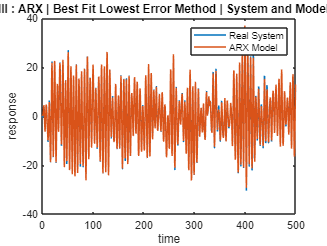

%%
figure()  % figure(1)
plot(t_val,y3_val,t_val,BestFit_y_hat_3)
legend('Real System','ARX Model')
title(" System III : ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

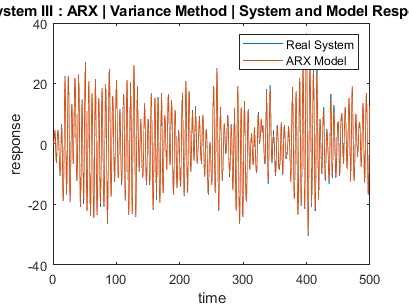


figure()  % figure(2)
plot(t_val,y3_val,t_val,Var_y_hat_3)
legend('Real System','ARX Model')
title(" System III : ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

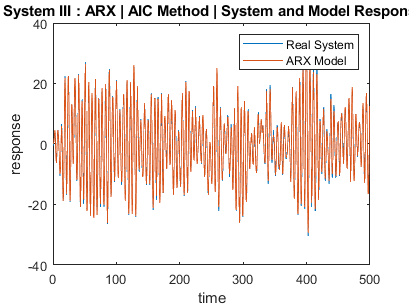


figure()  % figure(3)
plot(t_val,y3_val,t_val,AIC_y_hat_3)
legend('Real System','ARX Model')
title(" System III : ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

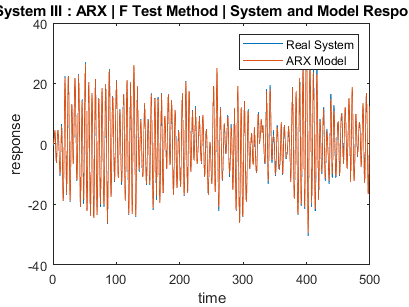


figure()  % figure(4)
plot(t_val,y3_val,t_val,FTest_y_hat_3)
legend('Real System','ARX Model')
title(" System III : ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")


% figure()  % figure(7)
% plot(t,y_val,t,Cov_y_hat)
% legend('Real System','ARX Model')
% title(" System III : ARX | Covariance Method | System and Model Response")
% xlabel("time")
% ylabel("response")


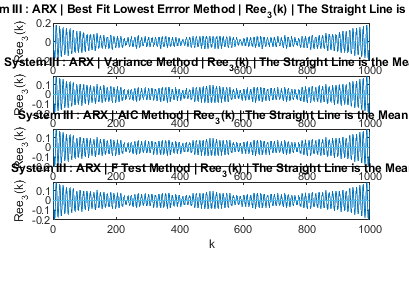

%%

figure()  % figure(5)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Ree_3(2:end), 1:N_val-1, mean(BestFit_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | Best Fit Lowest Errror Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Ree_3(2:end), 1:N_val-1, mean(Var_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | Variance Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Ree_3(2:end), 1:N_val-1, mean(AIC_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | AIC Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Ree_3(2:end), 1:N_val-1, mean(FTest_Ree_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | F Test Method | Ree_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_3(k)")


% subplot(5,1,5)
% plot(1:N_val-1,Cov_Ree_3(2:end), 1:N_val-1, mean(Cov_Ree_3(2:end))*ones(length(1:N_val-1)))
% title(" System III : ARX | Covariance Method | Ree_3(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_3(k)")



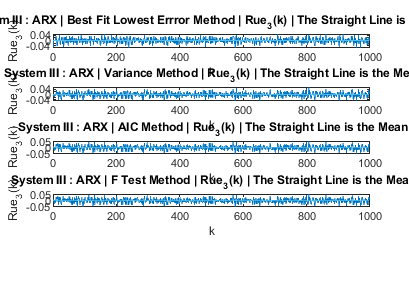

%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_3(2:end), 1:N_val-1, mean(BestFit_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | Best Fit Lowest Errror Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_3(2:end), 1:N_val-1, mean(Var_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | Variance Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_3(2:end), 1:N_val-1, mean(AIC_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | AIC Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_3(2:end), 1:N_val-1, mean(FTest_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" System III : ARX | F Test Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")



% subplot(5,1,5)
% plot(1:N_val-1,Cov_Rue_3(2:end), 1:N_val-1, mean(Cov_Rue_3(2:end))*ones(length(1:N_val-1)))
% title(" System III : ARX | Covariance Method | Rue_3(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_3(k)")




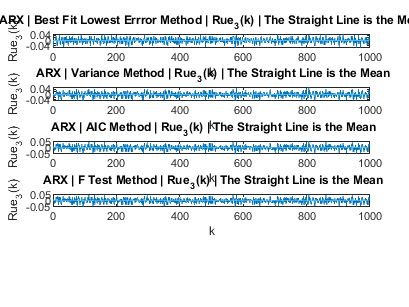

%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_3(2:end), 1:N_val-1, mean(BestFit_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" ARX | Best Fit Lowest Errror Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_3(2:end), 1:N_val-1, mean(Var_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" ARX | Variance Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_3(2:end), 1:N_val-1, mean(AIC_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" ARX | AIC Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_3(2:end), 1:N_val-1, mean(FTest_Rue_3(2:end))*ones(length(1:N_val-1)))
title(" ARX | F Test Method | Rue_3(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_3(k)")



% subplot(5,1,5)
% plot(1:N_val-1,Cov_Rue_3(2:end), 1:N_val-1, mean(Cov_Rue_3(2:end))*ones(length(1:N_val-1)))
% title(" ARX | Covariance Method | Rue_3(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_3(k)")


% ************************************************************************

fprintf("*****************************************************************\n")

*****************************************************************


fprintf("*****************************************************************\n")

*****************************************************************
